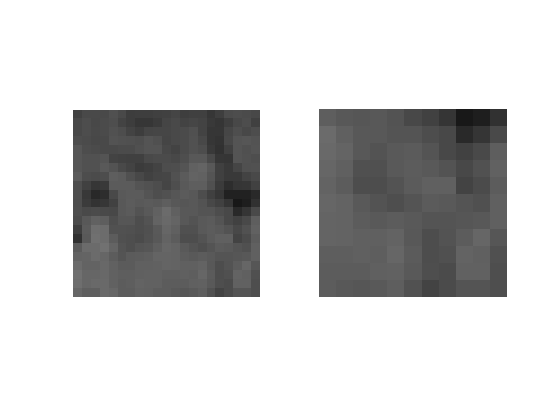

I=brain(130:150,150:170);
subplot(1,2,1);imshow(I)

I2=brain(140:150,160:170);
%I2 = imrotate(I,180);
subplot(1,2,2);imshow(I2)


%I = imread('/home/hemingy/Downloads/cat1.jpeg');

mapping=getmapping(4,'u2');
mapping

mapping = struct with fields:
      table: [0 1 2 3 4 14 5 6 7 8 14 9 10 11 12 13]
    samples: 4
        num: 15

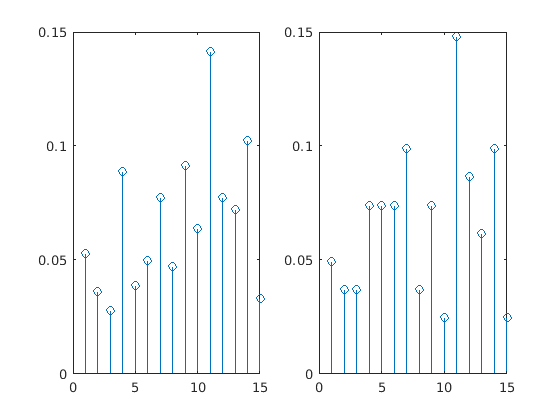


H1=lbp(I,1,4,mapping,'h'); %LBP histogram in (8,1) neighborhood
H1 = H1/sum(H1);
H2=lbp(I2,1,4,mapping,'h');
H2 = H2/sum(H2);
%using uniform patterns
figure;subplot(1,2,1),stem(H1);
subplot(1,2,2),stem(H2);

H1

H1 =     0.0526    0.0360    0.0277    0.0886    0.0388    0.0499    0.0776    0.0471    0.0914    0.0637    0.1413    0.0776    0.0720    0.1025    0.0332

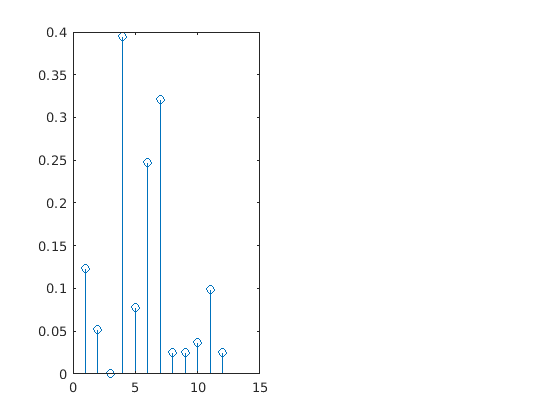

mapping=getmaplbphf(4);
h=lbp(I,1,4,mapping,'h');
h=h/sum(h);
histograms(1,:)=h;
h=lbp(imrotate(I,90),1,4,mapping,'h');
h=h/sum(h);
histograms(2,:)=h;
features = constructhf(histograms,mapping);
figure;subplot(1,2,1),stem(features(3,:));

features(1,:)

ans =     0.1496    0.0196         0    0.3712    0.0671    0.0886    0.2909    0.0083    0.0194    0.0526    0.1025    0.0332

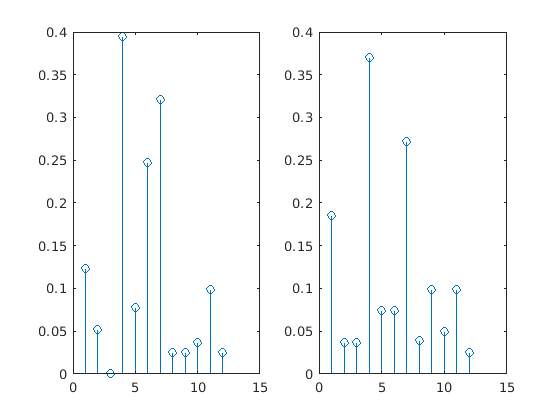

mapping=getmaplbphf(4);
h=lbp(I2,1,4,mapping,'h');
h=h/sum(h);
histograms(1,:)=h;
h=lbp(imrotate(I2,90),1,4,mapping,'h');
h=h/sum(h);
histograms(2,:)=h;

features = constructhf(histograms,mapping);
subplot(1,2,2),stem(features(1,:));

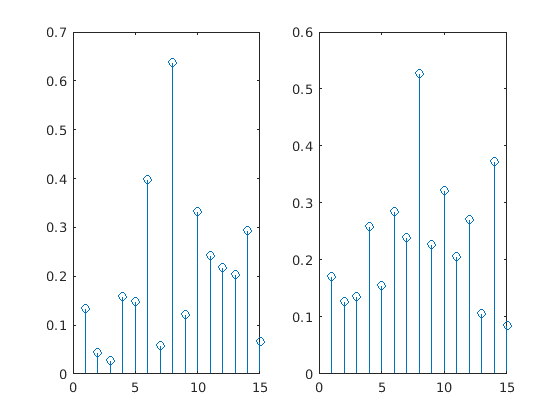

H3 = extractLBPFeatures(I,'NumNeighbors',4);
H4 = extractLBPFeatures(I2,'NumNeighbors',4);
figure;subplot(1,2,1),stem(H3);
subplot(1,2,2),stem(H4);

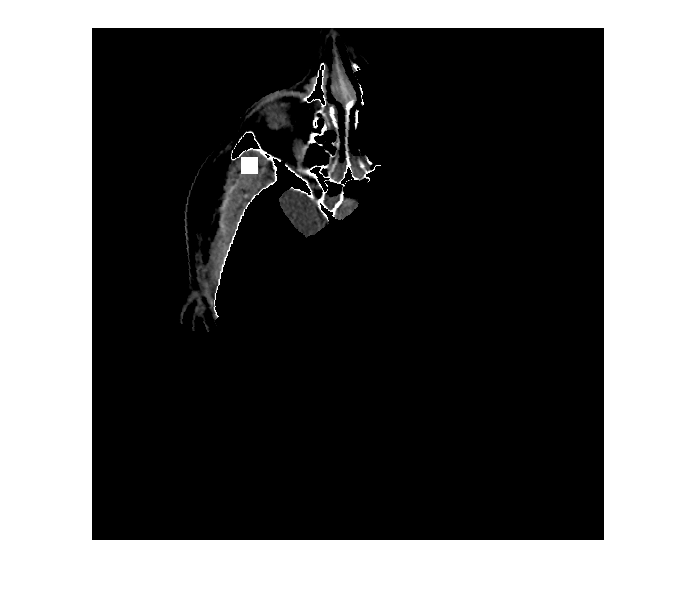

test = brain;
test(130:146,150:166)=255;
figure;imshow(test)